Nicolo Mega

EECE4512

Semester Project

Data Processing - EDG

close all 
clear vars 
clc
sampl_rate = 1000;
n_order = 5;
f_c = 5;

Import Daves Data Test 1 (D1)

%Morning Refresh
D1R=readmatrix('Davo Day 2 Morning Test.txt');
EDAD1R = D1R(:,7); %desired ecg output A2
TD1R = 1:length(D1R);
TD1R = TD1R/1000;

A = [TD1R', EDAD1R(:,1)];
writematrix(A,'test1.txt','Delimiter',' ');
type test1.txt

0.001 73
0.002 71
0.003 71
0.004 72
0.005 71
0.006 71
0.007 72
0.008 71
0.009 71
0.01 72
0.011 71
0.012 71
0.013 72
0.014 72
0.015 70
0.016 72
0.017 72
0.018 70
0.019 72
0.02 72
0.021 71
0.022 71
0.023 72
0.024 71
0.025 70
0.026 72
0.027 72
0.028 70
0.029 72
0.03 73
0.031 71
0.032 70
0.033 72
0.034 73
0.035 71
0.036 71
0.037 72
0.038 71
0.039 70
0.04 72
0.041 71
0.042 70
0.043 72
0.044 72
0.045 71
0.046 71
0.047 72
0.048 72
0.049 71
0.05 71
0.051 73
0.052 71
0.053 70
0.054 72
0.055 72
0.056 71
0.057 72
0.058 72
0.059 71
0.06 71
0.061 72
0.062 71
0.063 70
0.064 72
0.065 72
0.066 71
0.067 70
0.068 72
0.069 72
0.07 71
0.071 70
0.072 72
0.073 71
0.074 70
0.075 72
0.076 72
0.077 71
0.078 71
0.079 72
0.08 71
0.081 70
0.082 72
0.083 73
0.084 71
0.085 71
0.086 72
0.087 71
0.088 70
0.089 72
0.09 72
0.091 70
0.092 72
0.093 72
0.094 71
0.095 71
0.096 72
0.097 71
0.098 70
0.099 72
0.1 71
0.101 71
0.102 72
0.103 71
0.104 70
0.105 72
0.106 72
0.107 70
0.108 72
0.109 73
0.11 71
0.111 71
0.112 72
0.11


%Time = 0
D10=readmatrix('Davo Day 2 Afternoon before Test ECG andEDA Results.txt');
EDAD10 = D10(:,7); %desired ecg output A2
TD10 = 1:length(D10);
TD10 = TD10/1000;

A = [TD10', EDAD10(:,1)];
writematrix(A,'test2.txt','Delimiter',' ');
type test2.txt

0.001 245
0.002 244
0.003 245
0.004 244
0.005 245
0.006 245
0.007 245
0.008 244
0.009 245
0.01 244
0.011 245
0.012 244
0.013 245
0.014 244
0.015 245
0.016 244
0.017 245
0.018 244
0.019 245
0.02 244
0.021 245
0.022 245
0.023 245
0.024 244
0.025 245
0.026 245
0.027 245
0.028 245
0.029 244
0.03 245
0.031 244
0.032 245
0.033 244
0.034 245
0.035 245
0.036 244
0.037 245
0.038 244
0.039 244
0.04 244
0.041 244
0.042 244
0.043 245
0.044 244
0.045 245
0.046 244
0.047 245
0.048 244
0.049 244
0.05 245
0.051 245
0.052 245
0.053 244
0.054 245
0.055 244
0.056 245
0.057 244
0.058 245
0.059 244
0.06 245
0.061 244
0.062 245
0.063 245
0.064 245
0.065 244
0.066 245
0.067 244
0.068 245
0.069 244
0.07 245
0.071 245
0.072 245
0.073 245
0.074 244
0.075 245
0.076 244
0.077 245
0.078 245
0.079 245
0.08 245
0.081 245
0.082 245
0.083 245
0.084 244
0.085 245
0.086 244
0.087 244
0.088 244
0.089 245
0.09 245
0.091 245
0.092 245
0.093 245
0.094 245
0.095 245
0.096 245
0.097 244
0.098 245
0.099 244
0.1 245
0.101 244
0


%Time = 10
D11=readmatrix('Davo Day 2 AFTERNOON TEST 1 ECG AND EDA.txt');
EDAD11 = D11(:,7); %desired ecg output A2
TD11 = 1:length(D11);
TD11 = TD11/1000;

A = [TD11', EDAD11(:,1)];
writematrix(A,'test3.txt','Delimiter',' ');
type test3.txt

0.001 190
0.002 190
0.003 191
0.004 191
0.005 191
0.006 190
0.007 191
0.008 191
0.009 191
0.01 191
0.011 191
0.012 191
0.013 191
0.014 191
0.015 191
0.016 191
0.017 191
0.018 191
0.019 191
0.02 191
0.021 191
0.022 191
0.023 190
0.024 191
0.025 191
0.026 191
0.027 191
0.028 191
0.029 191
0.03 191
0.031 191
0.032 191
0.033 190
0.034 191
0.035 191
0.036 191
0.037 191
0.038 191
0.039 191
0.04 191
0.041 191
0.042 191
0.043 191
0.044 191
0.045 191
0.046 191
0.047 191
0.048 191
0.049 191
0.05 191
0.051 191
0.052 191
0.053 191
0.054 191
0.055 191
0.056 191
0.057 191
0.058 191
0.059 191
0.06 191
0.061 191
0.062 191
0.063 191
0.064 191
0.065 191
0.066 191
0.067 191
0.068 191
0.069 191
0.07 191
0.071 191
0.072 191
0.073 191
0.074 191
0.075 191
0.076 191
0.077 191
0.078 191
0.079 191
0.08 191
0.081 191
0.082 191
0.083 191
0.084 191
0.085 191
0.086 191
0.087 191
0.088 191
0.089 191
0.09 191
0.091 191
0.092 191
0.093 191
0.094 191
0.095 191
0.096 191
0.097 191
0.098 191
0.099 191
0.1 191
0.101 191
0


%Time = 20
D12=readmatrix('Davo Day 2 AFTERNOON TEST 2 ECG AND EDA.txt');
EDAD12 = D12(:,7); %desired ecg output A2
TD12 = 1:length(D12);
TD12 = TD12/1000;

A = [TD12', EDAD12(:,1)];
writematrix(A,'test4.txt','Delimiter',' ');
type test4.txt

0.001 190
0.002 190
0.003 190
0.004 189
0.005 189
0.006 189
0.007 189
0.008 189
0.009 189
0.01 189
0.011 190
0.012 190
0.013 190
0.014 190
0.015 190
0.016 190
0.017 189
0.018 189
0.019 189
0.02 188
0.021 189
0.022 190
0.023 190
0.024 190
0.025 190
0.026 190
0.027 189
0.028 189
0.029 189
0.03 188
0.031 189
0.032 190
0.033 190
0.034 190
0.035 190
0.036 190
0.037 190
0.038 189
0.039 189
0.04 189
0.041 188
0.042 190
0.043 190
0.044 190
0.045 190
0.046 190
0.047 189
0.048 189
0.049 189
0.05 189
0.051 189
0.052 190
0.053 190
0.054 190
0.055 190
0.056 190
0.057 190
0.058 190
0.059 190
0.06 190
0.061 189
0.062 189
0.063 189
0.064 189
0.065 189
0.066 189
0.067 190
0.068 190
0.069 190
0.07 190
0.071 190
0.072 189
0.073 189
0.074 189
0.075 189
0.076 189
0.077 190
0.078 190
0.079 190
0.08 190
0.081 190
0.082 190
0.083 190
0.084 190
0.085 190
0.086 189
0.087 189
0.088 189
0.089 189
0.09 190
0.091 190
0.092 190
0.093 190
0.094 190
0.095 190
0.096 190
0.097 190
0.098 190
0.099 190
0.1 189
0.101 190
0



%Time = 30
D13=readmatrix('Davo Day 2 AFTERNOON TEST 3 ECG AND EDA.txt');
EDAD13 = D13(:,7); %desired ecg output A2
TD13 = 1:length(D13);
TD13 = TD13/1000;

A = [TD13', EDAD13(:,1)];
writematrix(A,'test5.txt','Delimiter',' ');
type test5.txt

0.001 196
0.002 197
0.003 197
0.004 197
0.005 197
0.006 197
0.007 197
0.008 197
0.009 198
0.01 198
0.011 197
0.012 198
0.013 197
0.014 196
0.015 196
0.016 196
0.017 197
0.018 197
0.019 197
0.02 197
0.021 197
0.022 197
0.023 197
0.024 197
0.025 197
0.026 197
0.027 197
0.028 198
0.029 196
0.03 196
0.031 196
0.032 196
0.033 196
0.034 197
0.035 197
0.036 197
0.037 197
0.038 197
0.039 197
0.04 197
0.041 197
0.042 197
0.043 197
0.044 197
0.045 197
0.046 197
0.047 197
0.048 197
0.049 198
0.05 198
0.051 197
0.052 198
0.053 198
0.054 197
0.055 197
0.056 196
0.057 196
0.058 196
0.059 196
0.06 197
0.061 197
0.062 197
0.063 197
0.064 197
0.065 197
0.066 197
0.067 197
0.068 197
0.069 197
0.07 197
0.071 197
0.072 197
0.073 197
0.074 198
0.075 198
0.076 197
0.077 197
0.078 196
0.079 196
0.08 196
0.081 196
0.082 196
0.083 196
0.084 196
0.085 197
0.086 197
0.087 197
0.088 197
0.089 197
0.09 198
0.091 197
0.092 197
0.093 197
0.094 197
0.095 198
0.096 197
0.097 198
0.098 197
0.099 197
0.1 197
0.101 196
0


%Time = 40
D14=readmatrix('Davo Day 2 AFTERNOON TEST 4 ECG AND EDA.txt');
EDAD14 = D14(:,7); %desired ecg output A2
TD14 = 1:length(D14);
TD14 = TD14/1000;

A = [TD14', EDAD14(:,1)];
writematrix(A,'test6.txt','Delimiter',' ');
type test6.txt

0.001 190
0.002 190
0.003 189
0.004 188
0.005 189
0.006 190
0.007 190
0.008 190
0.009 190
0.01 189
0.011 189
0.012 189
0.013 190
0.014 190
0.015 190
0.016 189
0.017 189
0.018 189
0.019 190
0.02 190
0.021 190
0.022 190
0.023 190
0.024 190
0.025 190
0.026 190
0.027 190
0.028 190
0.029 190
0.03 190
0.031 190
0.032 190
0.033 190
0.034 190
0.035 190
0.036 190
0.037 190
0.038 190
0.039 190
0.04 190
0.041 190
0.042 190
0.043 190
0.044 189
0.045 190
0.046 190
0.047 190
0.048 190
0.049 189
0.05 190
0.051 190
0.052 190
0.053 189
0.054 190
0.055 190
0.056 190
0.057 190
0.058 190
0.059 190
0.06 189
0.061 190
0.062 190
0.063 190
0.064 190
0.065 189
0.066 190
0.067 190
0.068 190
0.069 190
0.07 190
0.071 189
0.072 190
0.073 190
0.074 190
0.075 190
0.076 189
0.077 189
0.078 190
0.079 190
0.08 190
0.081 190
0.082 190
0.083 190
0.084 190
0.085 190
0.086 190
0.087 190
0.088 190
0.089 189
0.09 190
0.091 190
0.092 190
0.093 190
0.094 190
0.095 190
0.096 189
0.097 190
0.098 190
0.099 190
0.1 190
0.101 189
0


%Time = 50
D15=readmatrix('Davo Day 2 AFTERNOON TEST 5 ECG AND EDA.txt');
EDAD15 = D15(:,7); %desired ecg output A2
TD15 = 1:length(D15);
TD15 = TD15/1000;

A = [TD15', EDAD15(:,1)];
writematrix(A,'test7.txt','Delimiter',' ');
type test7.txt

0.001 173
0.002 173
0.003 174
0.004 173
0.005 174
0.006 173
0.007 174
0.008 173
0.009 174
0.01 173
0.011 174
0.012 173
0.013 174
0.014 173
0.015 174
0.016 174
0.017 173
0.018 174
0.019 173
0.02 174
0.021 173
0.022 174
0.023 174
0.024 173
0.025 174
0.026 173
0.027 174
0.028 173
0.029 174
0.03 173
0.031 174
0.032 173
0.033 174
0.034 173
0.035 174
0.036 174
0.037 173
0.038 174
0.039 173
0.04 174
0.041 173
0.042 174
0.043 174
0.044 173
0.045 174
0.046 173
0.047 174
0.048 174
0.049 173
0.05 174
0.051 174
0.052 173
0.053 174
0.054 173
0.055 174
0.056 173
0.057 174
0.058 174
0.059 173
0.06 174
0.061 173
0.062 174
0.063 173
0.064 174
0.065 173
0.066 174
0.067 173
0.068 174
0.069 173
0.07 174
0.071 174
0.072 174
0.073 174
0.074 173
0.075 174
0.076 173
0.077 174
0.078 173
0.079 174
0.08 173
0.081 174
0.082 173
0.083 174
0.084 173
0.085 174
0.086 173
0.087 174
0.088 174
0.089 173
0.09 174
0.091 173
0.092 174
0.093 173
0.094 174
0.095 174
0.096 173
0.097 174
0.098 173
0.099 174
0.1 174
0.101 173
0


%Time = 60
D16=readmatrix('Davo Day 2 AFTERNOON TEST 6 ECG AND EDA.txt');
EDAD16 = D16(:,7); %desired ecg output A2
TD16 = 1:length(D16);
TD16 = TD16/1000;

A = [TD16', EDAD16(:,1)];
writematrix(A,'test8.txt','Delimiter',' ');
type test8.txt

0.001 250
0.002 251
0.003 251
0.004 251
0.005 250
0.006 251
0.007 251
0.008 251
0.009 250
0.01 251
0.011 251
0.012 251
0.013 250
0.014 250
0.015 251
0.016 251
0.017 250
0.018 250
0.019 251
0.02 251
0.021 250
0.022 250
0.023 251
0.024 251
0.025 251
0.026 250
0.027 251
0.028 251
0.029 251
0.03 250
0.031 251
0.032 251
0.033 251
0.034 250
0.035 250
0.036 251
0.037 251
0.038 251
0.039 250
0.04 251
0.041 251
0.042 251
0.043 251
0.044 250
0.045 251
0.046 251
0.047 251
0.048 251
0.049 251
0.05 251
0.051 251
0.052 251
0.053 250
0.054 251
0.055 251
0.056 251
0.057 251
0.058 250
0.059 251
0.06 251
0.061 250
0.062 250
0.063 251
0.064 251
0.065 251
0.066 250
0.067 251
0.068 251
0.069 251
0.07 251
0.071 250
0.072 251
0.073 251
0.074 251
0.075 250
0.076 251
0.077 251
0.078 251
0.079 250
0.08 250
0.081 251
0.082 251
0.083 251
0.084 250
0.085 250
0.086 251
0.087 251
0.088 250
0.089 250
0.09 251
0.091 251
0.092 251
0.093 250
0.094 251
0.095 251
0.096 251
0.097 250
0.098 250
0.099 251
0.1 251
0.101 251
0

Filter and Plot

Refreshed State

eda_data_filtered = lowpass_filter(EDAD1R, sampl_rate, n_order,f_c);
subplot(4,2,1)
plot(TD1R,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance - Refreshed State')

Time = 0 min

eda_data_filtered = lowpass_filter(EDAD10, sampl_rate, n_order,f_c);
subplot(4,2,2)
plot(TD10,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 0min')

Time = 10 min

eda_data_filtered = lowpass_filter(EDAD11, sampl_rate, n_order,f_c);
subplot(4,2,3)
plot(TD11,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 10min')

Time = 20 min

eda_data_filtered = lowpass_filter(EDAD12, sampl_rate, n_order,f_c);
subplot(4,2,4)
plot(TD12,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 20min')

Time = 30 min

eda_data_filtered = lowpass_filter(EDAD13,sampl_rate, n_order,f_c);
subplot(4,2,5)
plot(TD13,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 30min')

Time = 40 min

eda_data_filtered = lowpass_filter(EDAD14,sampl_rate, n_order,f_c);
subplot(4,2,6)
plot(TD14,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 40min')

Time = 50 min

eda_data_filtered = lowpass_filter(EDAD15, sampl_rate, n_order,f_c);
subplot(4,2,7)
plot(TD15,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 50min')

Time = 60 min

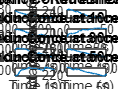

eda_data_filtered = lowpass_filter(EDAD16, sampl_rate, n_order,f_c);
subplot(4,2,8)
plot(TD16,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 60min')

Filter Function 

function data_filtered = lowpass_filter(data, sampl_rate, n_order,f_c);
[b_low,a_low] = butter(n_order,f_c/sampl_rate,'low');
data_filtered = filtfilt(b_low,a_low,data);
end